**EE 150**

**Signals and Systems**

** Lab 6 Laplace Transform**

Date Performed: 

Name & ID:

Suppose there is a system as shown in the figure below. The input of the system is $f\left(t\right)=$$u\left(t\right)$, the output of the system is $y_2 \left(t\right)=\left(3e^{-2t} -{4e}^{-3t} +1\right)u\left(t\right)$. Subsystem  $H_1$ can be represented by transfer function $H_1 \left(s\right)=\frac{6\cdot s}{\left(s+1\right)\cdot \left(s+2\right)}$, and subsystem $H_3 \left(s\right)=\frac{s+2}{3\cdot \left(s+1\right)}$. Subsystem  $H_2$ is unknown. Complete questions 1-5 according to the conditions.

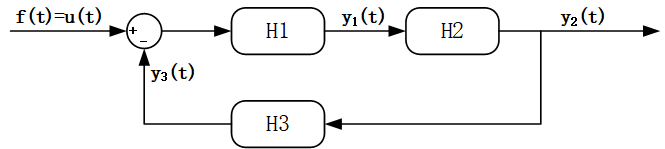

1. Write down the differential equations of the subsystem $H_1$. Find impulse response $h_1 \left(t\right)$ and display it.

Ans: The differential equations is y''(t)+3y'(t)+2y(t)=6x'(t)

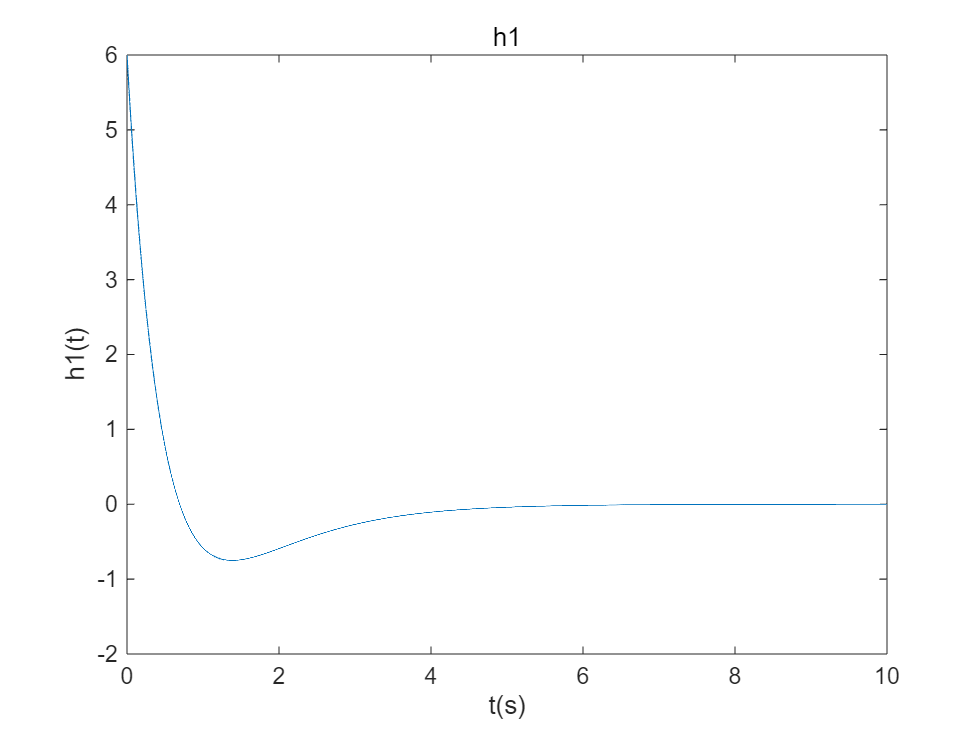

clear;clf;

t=0:0.001:10;
H1s = tf([6,0],[1,3,2]);
h1 = impulse(H1s,t);
 plot(t,h1);
 axis([0,10,0,1]);ylim([-2 6]); title("h1"); xlabel("t(s)"); ylabel("h1(t)");

;

2. Solve $y_1 \left(t\right)$ for the zero-state response of the subsystem $H_1$ using the Laplace transform and inverse Laplace transform.

Plot both incentive and response of subsystem $H_1$ with suitable display range.  


syms t s; 
ft=heaviside(t);
fplot(ft); hold on;
H1=(6*s)/((s+1)*(s+2));
y2=(3*exp(-2*t)-4*exp(-3*t)+1)*heaviside(t);
Fs=laplace(ft);
Y2=laplace(y2);

H3=(s+2)/(3*(s+1));
Y1=(Fs-Y2*H3)*H1

$$Y1 = \frac{6\,s\,\left(\frac{1}{s}-\frac{\left(s+2\right)\,\left(\frac{3}{s+2}-\frac{4}{s+3}+\frac{1}{s}\right)}{3\,s+3}\right)}{\left(s+1\right)\,\left(s+2\right)}$$

y1=ilaplace(Y1)* heaviside(t)

$$y1 = \mathrm{heaviside}\left(t\right)\,\left(6\,{\mathrm{e}}^{-2\,t}-6\,{\mathrm{e}}^{-3\,t}\right)$$

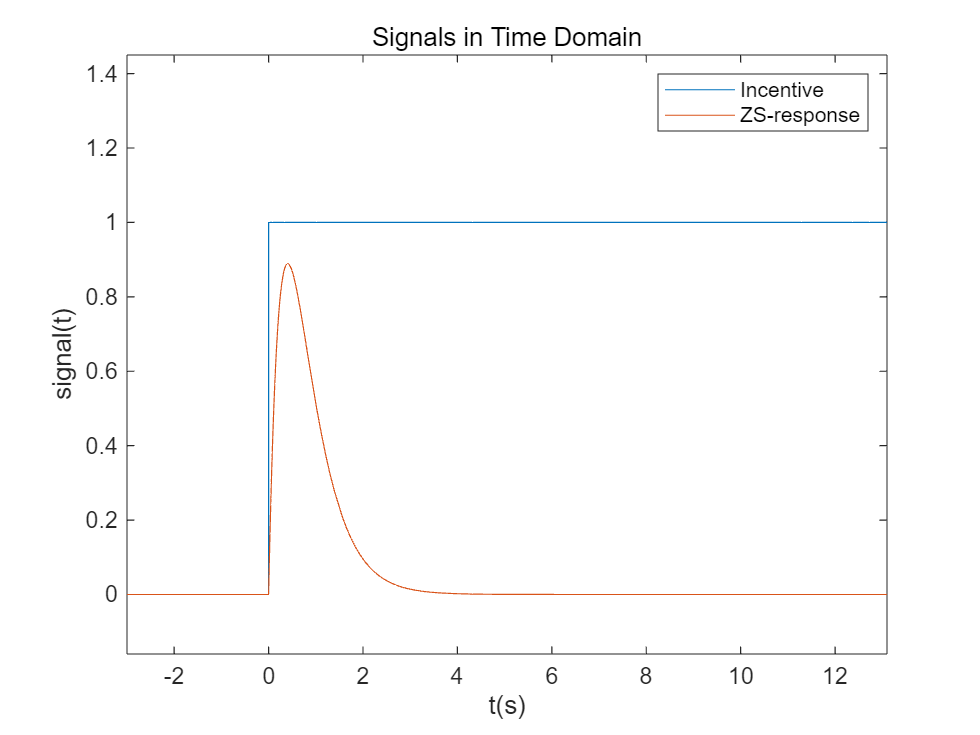

fplot(y1); xlim([0,10]); hold off;
 title('Signals in Time Domain');
 xlabel('t(s)'); ylabel('signal(t)');
 legend('Incentive','ZS-response');

xlim([-3.0 13.1])
ylim([-0.16 1.45])

3. Laplace transform and Fourier transform

a) What is the relationship between Laplace transform and Fourier transform? Answer the question in text. 

b) Plot the Laplace transform (3D) and  Fourier transform (2D) for $y_1 \left(t\right)$. 

c) Adjust axis range and the observation angle of the 3D surface. Display the relationship between Laplace transform and Fourier Transform.

(a) The Fourier transform is a special case of the Laplace transform. When the real part of s is zero (σ=0), the Laplace transform becomes the Fourier transform:

The Laplace transform converges in a region of the complex plane known as the Region of Convergence (ROC). If the ROC includes the imaginary axis (σ=0*σ*=0), then the Fourier transform of the function exists and is simply the Laplace transform evaluated on the imaginary axis.

For a system to be stable and causal, its Laplace transform must have all its poles in the left half of the complex plane (σ<0*σ*<0). If this condition is met, the Fourier transform will exist, and the system will be stable.

Both transforms are used to analyze systems in the frequency domain. The Fourier transform is used to analyze the frequency content of a signal, while the Laplace transform is used to analyze both the frequency and the damping (or growth) of the signal.

figure;
 x = -5:0.24:5; y = -3:0.19:3;
 [sigma,omega] = meshgrid(x,y);
 s = sigma+1j*omega;
Y1=simplify(Y1)

$$Y1 = \frac{6}{s^{2}+5\,s+6}$$

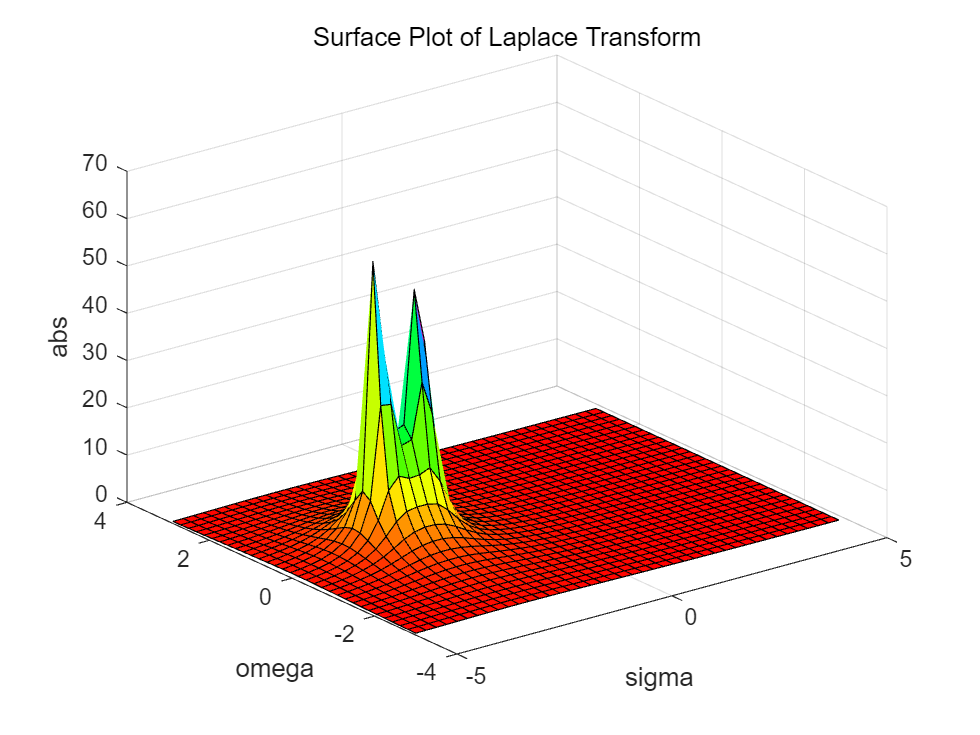

Y11=(6)./((s+2).*(s+3));
 Fsabs = abs(Y11);

surf(sigma,omega,Fsabs);
 xlabel('sigma');ylabel('omega');zlabel('abs')
 title('Surface Plot of Laplace Transform');
 colormap(hsv);
 
 rotate3d on;


 Y1ft = fourier(y1)

$$Y1ft = \frac{6}{2+w\,\mathrm{i}}-\frac{6}{3+w\,\mathrm{i}}$$

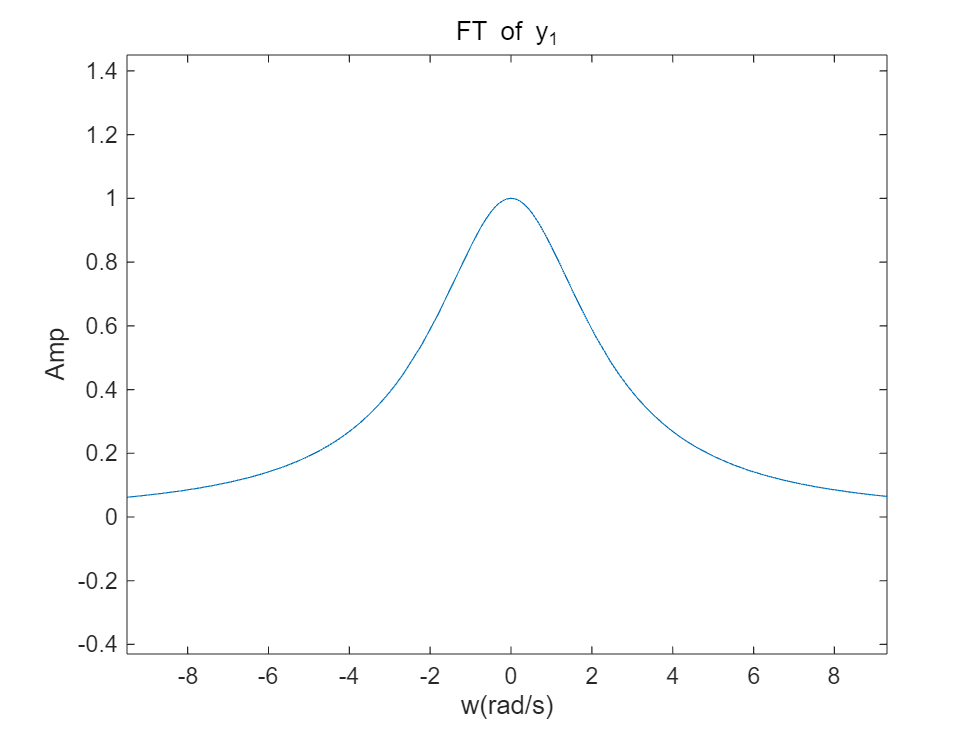



 fplot(abs(Y1ft)); axis([-3,3,0,0.6]); xlabel("w(rad/s)"); ylabel("Amp"); title("FT of y_1");

xlim([-9.5 9.3])
ylim([-0.43 1.45])

4. Confirm the system transfer function $H_2 \left(s\right)$ of the subsystem $H_2$ with code and write down it in text.

Tip: Use  ***simplified_expr = simplifyFraction(expr)*** to simplify the expression.

Ans: $H_2 \left(s\right)=$$\frac{s+1}{s}$

syms s;
H1=(6*s)/((s+1)*(s+2));
 Y3=Y2*H3

$$Y3 = \frac{\left(s+2\right)\,\left(\frac{3}{s+2}-\frac{4}{s+3}+\frac{1}{s}\right)}{3\,s+3}$$

E=Fs-Y3;
Y1=E*H1;
H2=Y2/Y1

$$H2 = \frac{\left(s+1\right)\,\left(s+2\right)\,\left(\frac{3}{s+2}-\frac{4}{s+3}+\frac{1}{s}\right)}{6\,s\,\left(\frac{1}{s}-\frac{\left(s+2\right)\,\left(\frac{3}{s+2}-\frac{4}{s+3}+\frac{1}{s}\right)}{3\,s+3}\right)}$$

H2=simplify(H2)

$$H2 = \frac{s+1}{s}$$

5. Stability

(a) Try to find out weather the three subsystems are stable or not?

They are all tsable.

(b) Is the whole system stable or not? Why?

Since  it is a right sided signal and the poles are all in the left side of jw-axis, thus the whole system is stable.

tips: The transfer function of the whole system is $H\left(s\right)=\frac{H_1 \cdot H_2 }{1+H_1 \cdot H_2 \cdot H_3 }$

H=simplify((H1*H2)/(1+H1*H2*H3))

$$H = \frac{6\,s+6}{s^{2}+5\,s+6}$$

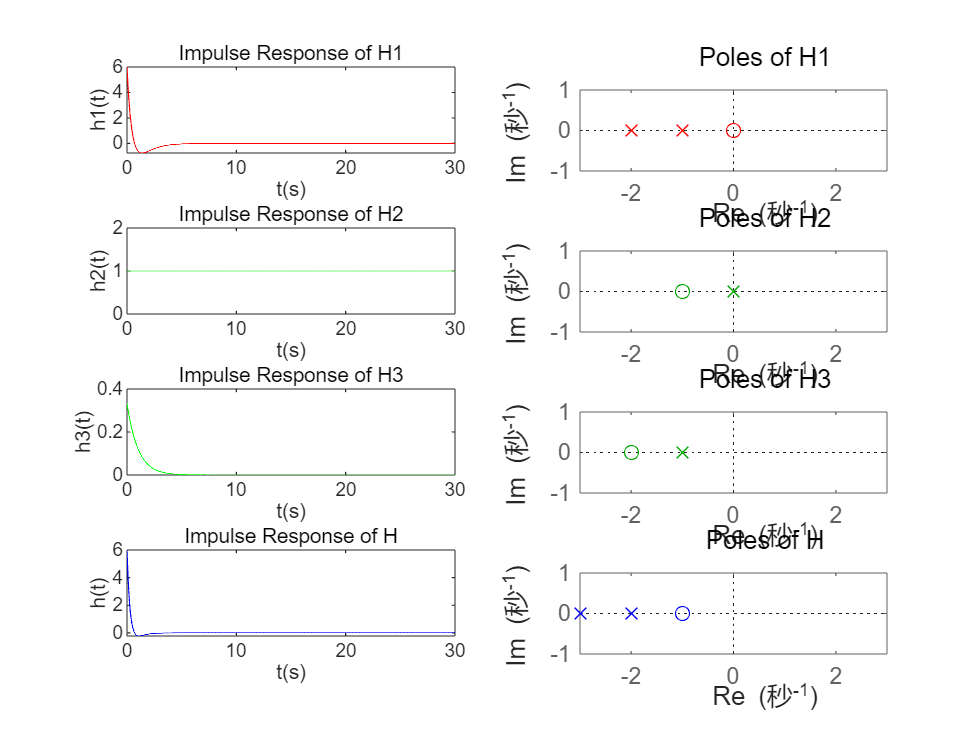

figure; clf;
t = 0:0.01:30;
c = ['r', 'g', 'b'];

% H1
b = [6, 0];
a = [1, 3, 2];
sys1 = tf(b, a);
subplot(4, 2, 1); plot(t, impulse(sys1, t), 'r'); xlabel('t(s)'); ylabel('h1(t)');
title('Impulse Response of H1'); xlim([0, 30]);

% Poles of H1
subplot(4, 2, 2);
hold on;
pzplot(sys1, c(1));
xlabel('Re'); ylabel('Im'); title('Poles of H1');
xlim([-3, 3]);
hold off;

% H2
b = [1, 1];
a = [1, 0];
sys2 = tf(b, a);
subplot(4, 2, 3); plot(t, impulse(sys2, t), 'g'); xlabel('t(s)'); ylabel('h2(t)');
title('Impulse Response of H2'); xlim([0, 30]);

% Poles of H2
subplot(4, 2, 4);
hold on;
pzplot(sys2, c(2));
xlabel('Re'); ylabel('Im'); title('Poles of H2');
xlim([-3, 3]);
hold off;

% H3
b = [1, 2];
a = [3, 3];
sys2 = tf(b, a);
subplot(4, 2, 5); plot(t, impulse(sys2, t), 'g'); xlabel('t(s)'); ylabel('h3(t)');
title('Impulse Response of H3'); xlim([0, 30]);

% Poles of H3
subplot(4, 2, 6);
hold on;
pzplot(sys2, c(2));
xlabel('Re'); ylabel('Im'); title('Poles of H3');
xlim([-3, 3]);
hold off;

% H
b = [6, 6];
a = [1, 5, 6];
sys3 = tf(b, a);
subplot(4, 2, 7); plot(t, impulse(sys3, t), 'b'); xlabel('t(s)'); ylabel('h(t)');
title('Impulse Response of H'); xlim([0, 30]);



% Poles of H3
subplot(4, 2, 8);
hold on;
pzplot(sys3, c(3));
xlabel('Re'); ylabel('Im'); title('Poles of H');
xlim([-3, 3]);
hold off;